# **AERO21111 Space Systems - MATLAB Tutorial 1 Answer**

## Introduction

This LiveScript covers the response to MATLAB tutorial 1 as required for the AERO21111 Space Systems module. During the course of this document I will analyse the overall performance characteristics for propulstion systems across a range of performance values in terms of the achievable change of velocity and fuel requirements. This broad analysis will then be used to solve a specific challenge in relation to the launch mass of the NASA/ESA Sentinal-6B spacecraft. The final step will then be to consider the results of this analysis in conjunciton with broader data on launcher performance across multiple areas to identify the most suitable vehicle to place the spacecraft into orbit.

# Propulsion Sensitivity and Mission Analysis

### Task 1 - Identify the Appropriate Equation

The total change in velocity$\Delta v$ requirements for a manoeuvre can be given as described in equation 5.31 of the course notes and shown below:

####             
$$\Delta v = \Delta v_{ideal} - \Delta v_D - \Delta v_g$$
 

Assuming that as the required manoeuvre is for a spacecraft already in orbit then there is no atmospheric drag loss $\Delta v_D$, and the loss due to gravitation $\Delta v_g$ is negligible as stated in the tutorial then: 

####              
$$\Delta v_D = \Delta v_g = 0$$
 

And so by extracting the relationship shown in equation 5.30 of the course notes it can be stated that the total change in velocity required for the Sentinal-6B orbital manoeuvre is given by:

####              
$$\Delta v = \Delta v_{ideal} = I_{sp}g \ln \frac{m_0}{m_1}$$


The constants and variables in this equation are:

- The specific impulse range:

####                 
$$I_{sp} = 200s - 300 s$$


- The range of required veloctiy changes:

####                 
$$\Delta v=1-2\;\textrm{km}/s$$


- The acceleration due to the Earth's gravity is 

####                 
$$g = 9.81\ m\ s^{-2}$$


- The initial mass of the spacecraft prior to the manoeuvre $m_o$ which can be given in terms of the dry mass $m_{dry}$ and the fuel mass $m_{fuel}$.

####                 
$$m_{0} = m_{dry} + m_{fuel}$$


- And the final mass of the spacecraft after the completion of the manoeuvre $m_{1}$ assuming that all fuel is expended is given soley by the dry mass as defined in the tutorial:

####                 
$$m_1 = m_{dry} = 1000\ kg$$


Inserting these values into equation 5.30 and rearranging to make $m_{fuel}$ the subject gives:

####                 
$$m_{fuel} = m_{dry} \left( e^{\frac{\Delta v}{I_{sp}g}} - 1 \right)$$


### Task 2 - Establish the input values

Now that we have identified the correct equation the required input values can be defined in code. First we will create constants for the dry mass and acceleration due to gravity (in appropriate units):

mdry          = 1000;                             %[kg] Dry mass of the satellite
g             = 9.81*10^(-3);                     %[km/s^2]

The next step it to define an input range for the specific inpulse and Delta v that will allow a range of analysis. In this case I have chosen to create an array for the specific impulse between 200 - 300 seconds with steps of 1 second, and for a change in velocity between 1 and 2 $km\ s^{-1}$ with steps of 0.01 $km\ s^{-1}$ as follows:

Isp           = linspace(200,300,101);            %[s] Specific impulse (100 increments)
DeltaV        = linspace(1,2,101);                %[km/s] Required velocity change (100 increments)

### Task 3 - Create the 2D Mesh

The 2D mesh can be created by applying the **meshgrid** command and using the vectors already defined for specific impulse and change in velocity. This will convert the vectors into equally sized arrays that are suitable for comparison and further analysis.

[ISP,DV]     = meshgrid(Isp,DeltaV);            % Creates an equally sized array for the ISP and velocity change ranges.

### Task 4 - Calculating the Required Fuel Mass

Now that we have the required input values we can use the equation already defined in task 1 to identify the required fuel mass across our range of specific impulses and velocity changes as follows:

mfuel         = mdry.*(exp(DV./(g.*ISP))-1);      %Calculating the fuel mass required in kg for a range of ISP and velocity changes.

### Task 5 - Generating the Surface Plot

To conduct the sensitivity analysis for the mass of fuel required in relation to a defined specific impulse and velocity change we can use the output of previous tasks to create a surface plot as follows:

surf(ISP,DV,mfuel)                                % Create a surface plot in terms of ISP, change in velocity and fuel mass
view(0,90)                                        % Display the plot in 2D

The final step in generating the plot is to ensure that it is clear and readable, with appropriate labels and a key to allow identification of output values

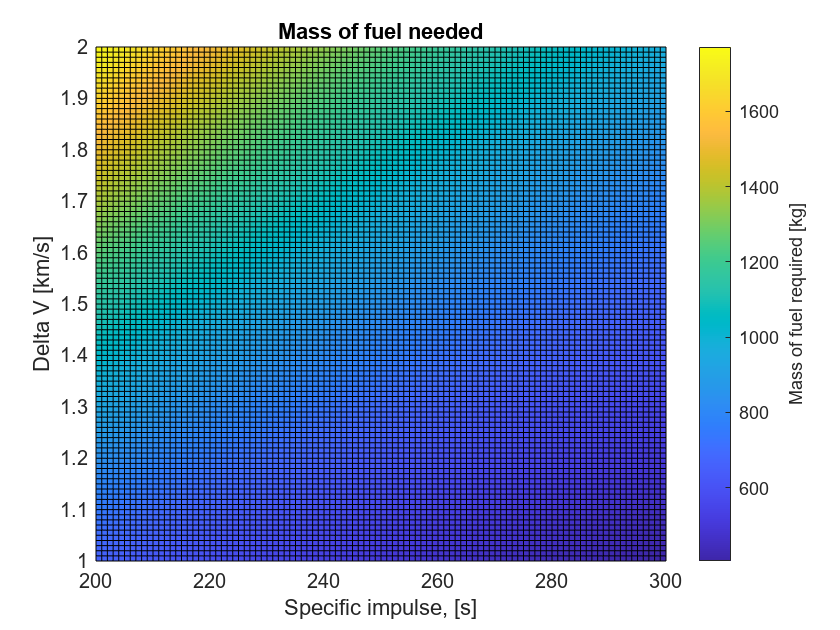

xlabel('Specific impulse, [s]')                   % Adds the required label to the x axis
ylabel('Delta V [km/s]')                          % Adds the required label to the y axis
title('Mass of fuel needed')                      % Adds an appropriate title
colorbar                                          % Generates a colorbar to the side of the surface plot
ylabel(colorbar, 'Mass of fuel required [kg]')    % Labels the colorbar in the vertical direction

If the LiveScript is now run up to this point a surface plot is generated showing the mass of fuel required in $kg$ against a specific impulse from 200 - 300 seconds and a velocity change between 1 and 2 $km\ s^{-1}$. A system engineer can use this plot and the peformance capability of the spacecraft engine to identify the fuel mass required to complete a manoeuvre involving a specific change in velocity.

### Task 6 - Identifying the Total Launch Mass

The tutorial question states that the planned manoeuvre for Sentinal-6B will require a change in velocity of $\Delta v = 1.3\ km \ s^{-1}$ and that the spacecraft thruster has a specific impulse of $I_{sp} = 230\ s$. Using the surface plot created in task 4 the required fuel mass in kg to perform the manoeuvre is: 

####                 
$$m_{fuel} = 779.201\ kg$$


The assumed spacecraft dry mass as given in the tutorial is:

####                 
$$m_{dry} = 1000\ kg$$


And so the total launch mass of the spacecraft required to perform the stated orbital manoeuvre can be estimated as: 

####                 
$$m_{total} = m_{dry} + m_{fuel} = 1779.201\ kg$$


Given that this is an early stage calculation I will add a fuel margin of approximately 10% and thus approximate the total mass as :

####                 
$$m_{\textrm{total}} =1850\textrm{kg}$$


### Task 7 - Selecting a Launch Vehicle

**Mass Requirements**. 

Table 1 in the tutorial shows that all the launch vehicles can place the required total mass into a polar orbit and so all are potential options at this point.

**Reliability Assessment**. 

Using the values provides the launch reliability of each vehicle has been calculated as follows:

    -    Falcon 9 $\approx 98.4\%$

    -    Ariane 5 $\approx 95.4 \%$

    -    Atlas V $\approx 98.9\%$

    -    Delta IV Medium $\approx 94.9\%$

As the Delta IV has a reliability below $95\%$, albeit on a much lower number of flights and accounting for the fact that most failiures happen early in a vehicles operational lifespan, I have chosen to discount that as an option at this point.

**Environmental Impact**. 

Based on the provided emissions values the remaining launch vehciles have been ranked in accordance with their oupt from low to high:

    -    CO2 emissions: 

                 1. Ariane 5

                 2. Atlas V 

                 3. Falcon 9

    -   H2O emissions:

                1. Ariane 5

                2. Atlas 5

                3. Falcon 9

And so it is clear that the Ariane 5 is the least polluting of the remaining launchers.

**Launch Site Selection**. 

The required orbital inclination of $66^0$ is achievable from all launch sites, however as it is in a prograde orbit this will likely require the initial direction of travel to be to the North East from the launch site to minimise launcher fuel expendature. This reduces the avaiable sites to:

    -    Kennedy Space Centre (CCAFS)

    -    Guiana Space Centre (FRGUI)

    -    Baikonur Cosmodrome (TYMSC)

The remaining launch vehicle options are operated by different states and so this limits the launch options as follows:

    -    Ariane 5: Guiana Space Centre (ESA)

    -    Atlas V: Kennedy Space Centre (United States)

    -    Falcon 9: Kennedy Space Centre (United States)

None of these vehicles are operated by the Russian Federation and so Baiknour Cosmodrome is discounted at this point.

A launch vehicle receives a boost from the Earth's rotation that increases in relation to the equatorial proximity of the launch site. In this case Guiana is the closest to the equator and so would receive the largest boost, although Kennedy would also receive some benefit to a lower factor.

**Final Launch Vehicle Selection**

Although the Falcon 9 and Atlas V both attain a greater reliability score than Ariane 5, this latter vehicle comes out on top in the analysis of environmental impact and launch site selection. Therefore the ESA Ariane 5 operating from Guiana Space Centre has been chosen as the preferred launch vehicle for the Sentinal-6B spacecraft based on these criteron.

### Summary and Conclusion

This LiveScript has covered the completion of tutorial 1 as part of the AERO21111 Space Systems MATLAB coursework. During the course of this assignment I have identified the required mathematical relationship between engine performance and fuel requirements based on a range of velocity changes. Using this relationship I have conducted a sensitivity analysis to provide a broad analysis and then applied it to assist in the solution of a specified problem. This was to find the fuel requirements for the Sentinal-6B spacecraft with a dry mass of 1000 kg able to perform a single velocity change of 1.3 $km\ s^{-1}$ using a thruster with an $I_{sp} = 230s$. This resulted in total launch mass of $\approx 1850\textrm{kg}$. Finally by combining the launch mass requirements along with the available launcher reliability, environmental impacts and launch site characteristics a judgement has been made as to the preferred launch provider. The result is that the preferred vehicle to launch Sentinal-6B into a prograde orbit at 66deg with minimal environmental impact is achieved by requesting the services of the ESA Ariane 5 capability operating out of Guiana Space Centre.

### References

Smith, K., and Macario-Rojas, A., 2023, 'Chapter 5: Propulsion & Launch Systems', *AERO21111 Space Systems Course Notes*, School of Engineering, The University of Manchester.

# **AERO21111 Space Systems - MATLAB Tutorial 2 Answer**

## Introduction

The provided livescript conducts an analysis of the thermal cycle experienced during the orbit trajectory of the Sentinel-6B spacecraft. The primary responsbility of this script is to generate a temperature profile, and raise component engineers' awareness regarding the thermal paramters of the spacecraft throughout orbit - Ensuring all temperature-sensitive components are engineered to endure and operate effectively within these specified thermal parameters. It is to be noted by component engineers that this scirpt does not reflects every influence that the space radiates with the spacecraft, and there will be some technical assumptions applied. We recommended that all data referenced here are mindful of those assumptions, and adhere on a 10% margin of safety to ensure operational functionality. [Precentage references to Mr Ian Muirhead's experience as a profressional engineer and lecturer] 

For all equations found in this livescirpt, please refer to "AERO21111 Space System" by Dr. Katharine Smith. 

# Propulsion Sensitivity and Mission Analysis

## **Task 1**

Define the given data for this mission - The appendix of thermo-physical constants and flight-parameter information.

Thermo physical data: 

% Thermo physical data:
q_s = 1400;     % [W m^-2] Solar radiation flux
q_e = 240;      % [W m^-2] Earth radiation flux
a_r = 0.3;      % [-] Earth Albedo 
sigma = 5.67e-8; % [W m^-2 K^-4] Stephan-Boltzmann constant
R_E = 6371e3;     % [m] Earth Radius
mu = 3.986e14;   % [m^3 s^-2] Standard gravitational parameter of Earth

Other necessary flight parameter data: 

% Other necessary flight parameter information: 
h = 1336e3;       % [m] Altitude
alpha = 0.46;      % [-] Material Absorptance 
varepilson = 0.77;  % [-] Spacecraft surface emittance
P_sun = 1000;      % [W] Heat dissipated by spacecraft during sunlit
P_eclipse = 500;   % [W] Heat dissipated by spacecraft during eclipse
A_surf = 3.35;     % [m^2] Surface area of one side
A_total = 3.35*6;  % [m^2] Total surface Area, assumed the satellite is a cube. 
c_p = 900;         % [Jkg^−1 K^−1] Specific heat capacity
T_i = -10;         % [C] Initial temperature 
m_total = 1850;     % [kg] Total mass found from tutorial 1

**Discussion Task:**

For this mission, a heater is added to our satellite to ensure it operates under operational temperature range. The heater is 5kg. The value of the power of the heater is 30W.

m_Heater    = 5;              %[kg] Mass of Heater 
P_Heater   = 30;              %[W] Power of Heater

### Task 2: Calculating Thermal Time Constant

Calculating Thermal Time Constant, applying equation 6.45 shown at the coursenote:

#### 
$$\tau_t =\frac{m_{\textrm{total}} c_p }{\varepsilon \sigma A_{\textrm{total}} }$$


$\tau_t$ = Thermal Time Constant

$m_{\textrm{total}}$= Total Mass of the spacecraft (derived from Tutorial 1)

$c_p$ = Specific heat capacity

$\varepsilon$ = Emittance

$\sigma$ = Stephan-Boltzmann constant

$A_{\textrm{total}}$ = Surface area of full spacecraft.

thermalTimeConstant = (m_total * c_p)/(sigma * varepilson * A_total); % [-] Thermal Time Constant

### Task 3: Calculating the Eclipse Duration for the satellite

First, calculatte orbit period $\tau$, assuming orbit is circular, the semi-major axis $\alpha$ equals to altitude $h$ + radius of Earth $R_E$

#### 
$$a=h+R_E \;$$


a = h + R_E; %[m] Semi Major Axis

Calculating orbit period using equation 3.9 of the coursenote:

#### 
$$\tau =2\pi \;\sqrt{\;\frac{a^3 }{\mu }}$$
 

$\mu$ = Standard gravitational parameter of Earth

tau = (2*pi*(sqrt(((a)^3)/mu))); %[s] Orbit Period    

Assuming the sun line is normal to the Earth's surface, the angle [Radian] which the spacecraft is in eclipse $\theta \;$is [Equation found on tutorial 2]:

#### 
$$\theta =\arcsin \left(\frac{R_e }{a}\right)$$


theta = asin(R_E/a); %[R] Angle of eclipse in radian

Using $\theta$ and applying an arc length formula, we can find the distance travelled in eclipse $D_e$ by using the semi major axis $a$.


$$D_e =a\left(2\theta \right)\;$$


D_eclipse = a*(2*theta); %[m] Arc length of eclipse

Applying variables solved above, creating a ratio of distance travelled in eclipse $D_e$ over circumference of orbit $2\pi a$ to find the eclipse fraction (Fraction of orbit spent in eclipse): 

#### 
$$\textrm{Eclipse}\;\textrm{Fraction}=\frac{D_e }{2\pi a}$$


eclipse_fraction = D_eclipse/(2*pi*a); %[] Fraction of Orbit spent in eclipse

Mutiplying the eclipse fraction with total orbit period $\tau$, we get the eclipse time by the following:

#### 
$$t_{\textrm{eclipse}} =\tau *\textrm{Eclipse}\;\textrm{Fraction}$$


t_eclipse = tau *eclipse_fraction; %[s] Eclipse duration

Subtracting the total time $\tau$ with eclipse time $t_{eclipse}$, we get the sun time $t_{sun}$ by the following:

#### 
$$t_{\textrm{sun}} =\tau -t_{\textrm{eclipse}} \;$$


t_sun = tau - t_eclipse; %[s] Non-eclipse duration

### Task 4: Thermal Power Input and Equilibrum temprature

The following section explains the calculation on thermal power input and thermal equilibrum during non-eclipse and eclipse orbit. 

To find the thermal power input during sun exposure, we assume the $\sum Heat$, $Q_{in$ is the following [Equation 6.37 in the course note]: 

#### 
$$Q_{\textrm{in}\;} =\textrm{Direct}\;\textrm{Solar}\;\textrm{Radiation}+\textrm{Albdeo}\;\textrm{Radiation}+\textrm{Earth}\;\textrm{Shine}+\textrm{Onboard}\;\textrm{Power}\;\textrm{Dissipation}$$


Where each terms could be calculated as: 


$$\textrm{Direct}\;\textrm{Solar}\;\textrm{Radiation}=q_s \alpha_s A_{s/c}^S$$


- $q_s$ = Solar radiation flux

- $\alpha_s$ = Absorbance of the spaceship's material 

- $A_{s/c}^S$ = Projected area of the spacecraft facing the Sun 

Q_solar = q_s * alpha * A_surf; %[W] Direct Solar Radiation


$$\textrm{Albdeo}\;\textrm{Radiation}=\;a_r q_s \alpha_s F_{12} \;A_{s/c}^P \cos \phi \;\cos \theta_s$$


-  $a_r$ = Earth albedo radiation

- $q_s$ = Solar radiation flux

- $\alpha_s$ = Absorbance of the spaceship's material 

- $F_{12}$ = View factor between the spacecraft and the planet, it is found using the following equation 6.23, 6.22 of the coursenote. 

- $R_R =\frac{h}{R_{\oplus } }$ ,${\;F}_{12} =\frac{\cos \theta }{{\left(1+R_R \right)}^2 }$ , where $R_R$ is Radius Ratio 

- $A_{s/c}^P$ = Projected area of the spacecraft facing the planet

- $\theta_s$ = Angle between ecliptic plane and orbit plane = 0 as assumption of sun line is normal to the surface. 

- $\phi$ Angle as measured for a co-planar orbit

R_R = h/R_E; %[] Radius Ratio
%Assume that it's a coplanar orbit.
phi_coPlanar = 0; %[Degree]
%Assume that the side facing the earth is tangent to the sun line...
theta_sun = 0; %[Degree] between the sun and the space. 
F12 = cos(theta_sun)/(1+R_R)^2; %[] View Factor 
Q_albedo = a_r*q_s*alpha*F12*A_surf *cos(phi_coPlanar)*cos(theta_sun); %[W] Albedo Radiation


$$\textrm{Earth}\;\textrm{Shine}=\;q_{\oplus } \varepsilon \;F_{12\;} A_{s/c}^P$$


- $q_{\oplus }$ = Earth radiated thermal energy 

- $\varepsilon \;$= Emissivity of the spacecraft 

- $F_{12\;}$= View factor denoted from above in Albedo Radiation [Same assumption]

- $A_{s/c}^P$ = Projected area of the spacecraft facing the planet 

Q_oplus =  q_e * varepilson * F12 * A_surf; %[W]Earth Shine 

$P_{dis}$ = $P_{eclipse}$ or $P_{sun}$ [Eclipse or non-eclipse] 

P_sun; %[W] This is a given data. 

Sum it all together, thermal power input during sun exposure is calculated using the following: 

Q_s = Q_solar+Q_albedo+Q_oplus+P_sun %[W] Thermal power input during non-eclipse phase of orbit.

Q_s = 4.0227e+03

To find the thermal power input during eclipse, we assume the $\sum Heat$, $Q_{e}$ is the following [Equation 6.37 in the course note]: 

### 
$$Q_e =q_{\oplus } A_{s/c}^P \varepsilon +P_{\textrm{sun}}$$


- $Q_e$ = Heat input during eclipse

- $q_{\oplus }$ = Earth radiated thermal energy 

- $A_{s/c}^P$ = Projected area of the spacecraft facing the planet 

- $\varepsilon \;$= Emissivity of the spacecraft 

- $P_{sun}$ =  Heat dissipated by spacecraft during sunlit

Q_e = q_e*A_surf*varepilson+P_eclipse; %[W] Thermal Input Power in eclipse.

Finding the $Q_H$ of heater: 

Q_H = Q_e * P_Heater; %[W] Thermal Input Power Of heater; 

Applying thermal input power, the equilibrium temperature can be calculated using the following: [Equation 6.40 of the course note]

### 
$$T_{\textrm{eq}} =\sqrt[4]{\frac{Q_{\textrm{in}} }{\varepsilon \sigma A_{\textrm{total}} }}$$


- $T_{\textrm{eq}}$= Equilibrium temprature

- $Q_{\textrm{in}}$ = Total thermal input power

- $\varepsilon \;$= Emissivity of the spacecraft 

- $A_{\textrm{total}}$is the total surface area of the satellite

T_eqs = (Q_s/(varepilson*sigma*A_total))^(1/4)           %[K] Equilibrium temperature during non-eclipse phase.

T_eqs = 260.2033

T_eqe = (Q_e/(varepilson*sigma*A_total))^(1/4)           %[K] Equilibrium temperature during eclipse phase.

T_eqe = 188.9722

T_eq_Heater = (Q_H/(varepilson * sigma * A_total))^(1/4) %[K] Equilibrium temperature for the heater

T_eq_Heater = 442.2605

### Task 5: Change in Temperature over Time

The following task explains the calculation behind the change of temperature of the satellite throughout orbit. 

% Initializing variables for simulation

iterations = 100;                   %Amount of timestep
systemTime = tau * iterations;      % Total Simulation Time
simulation_time = 0;                % Initializing Simulation Time
t_elasped = [];                     % Array for time elapsed
temp = T_i;                         % Initializing Temperature
temp_Heater= T_i;                   % Initializing Temperature
timeStep_counter = 0;                  % Tracking orbit count
t_orbit = 0;                        % Initializing Orbit time
dT = 0;                             % Initializing Change in Temperature
% Running the simulation loop for 50 orbits
while simulation_time <= systemTime
    timeStep_counter                = timeStep_counter + 1; 
    t_elasped(timeStep_counter)     = simulation_time;
    T_sat(timeStep_counter)         = temp;
    T_sat_Heater(timeStep_counter)  = temp_Heater; 

    % Assuming it begins on sunlight, 
    % Runs an if statement to determine when it reaches to eclipse. 
    % The if statements divide apporpiate equations and calculation needed.
    if t_orbit < t_sun
        simulation_time = simulation_time + (t_sun / iterations);
        t_orbit = t_orbit + (t_sun / iterations);  
        dT = (((T_eqs^4) - (temp^4)) / thermalTimeConstant) * (t_sun / iterations);
        dT_Heater = dT;
       
    % When the orbit enters eclipse phase of mission
    elseif t_orbit >= t_sun && t_orbit < tau
        t_orbit = t_orbit + (t_eclipse / iterations);
        simulation_time = simulation_time + (t_eclipse / iterations);
        dT = (((T_eqe)^4 - (temp)^4) / thermalTimeConstant) * (t_eclipse / iterations);
        dT_Heater = (((T_eq_Heater)^4 - (temp)^4) / thermalTimeConstant) * (t_eclipse / iterations);
       
    % If our time of orbit exceeds one orbit period, the spacecraft has
    % entered a new orbit and orbit time is redfined as 0; 
    elseif t_orbit >= tau
        t_orbit = 0;
    end
     temp = temp + dT;
        temp_Heater = temp_Heater + dT_Heater;
    disp(temp);
end

   -9.8877

   -9.7754

   -9.6631

   -9.5508

   -9.4385

   -9.3263

   -9.2140

   -9.1017

   -8.9894

   -8.8771

   -8.7648

   -8.6525

   -8.5402

   -8.4279

   -8.3156

   -8.2033

   -8.0910

   -7.9788

   -7.8665

   -7.7542

   -7.6419

   -7.5296

   -7.4173

   -7.3050

   -7.1927

   -7.0804

   -6.9681

   -6.8558

   -6.7435

   -6.6313

   -6.5190

   -6.4067

   -6.2944

   -6.1821

   -6.0698

   -5.9575

   -5.8452

   -5.7329

   -5.6206

   -5.5083

   -5.3960

   -5.2838

   -5.1715

   -5.0592

   -4.9469

   -4.8346

   -4.7223

   -4.6100

   -4.4977

   -4.3854

   -4.2731

   -4.1608

   -4.0485

   -3.9363

   -3.8240

   -3.7117

   -3.5994

   -3.4871

   -3.3748

   -3.2625

   -3.1502

   -3.0379

   -2.9256

   -2.8133

   -2.7010

   -2.5887

   -2.4765

   -2.3642

   -2.2519

   -2.1396

   -2.0273

   -1.9150

   -1.8027

   -1.6904

   -1.5781

   -1.4658

   -1.3535

   -1.2412

   -1.1290

   -1.0167

   -0.9044

   -0.7921

   -0.6798

   -

### Task 6: Plotting 

Below a time vs temperature graph is plotted, with the temperature values converted from Kelvin to Degrees Celcius

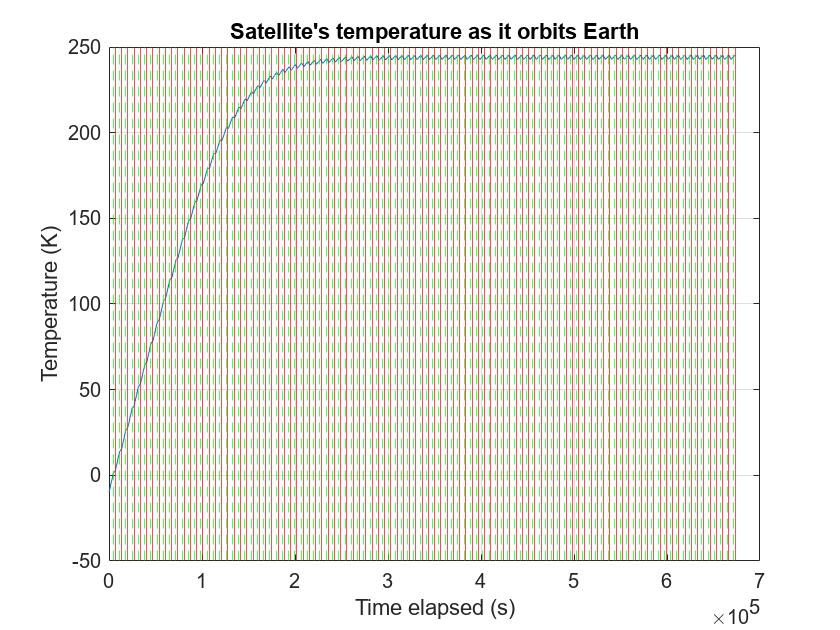

% Set up figure
figure
plot(t_elasped, T_sat) %In degree as operational functionality also in degree
hold on
xlabel("Time elapsed (s)")
ylabel("Temperature (K)")
title("Satellite's temperature as it orbits Earth")

% Add vertical lines for eclipse events
for i = 1:iterations
    xline(i * tau - t_eclipse, '--g')
    xline(i * tau, 'r')
end

grid on
hold off

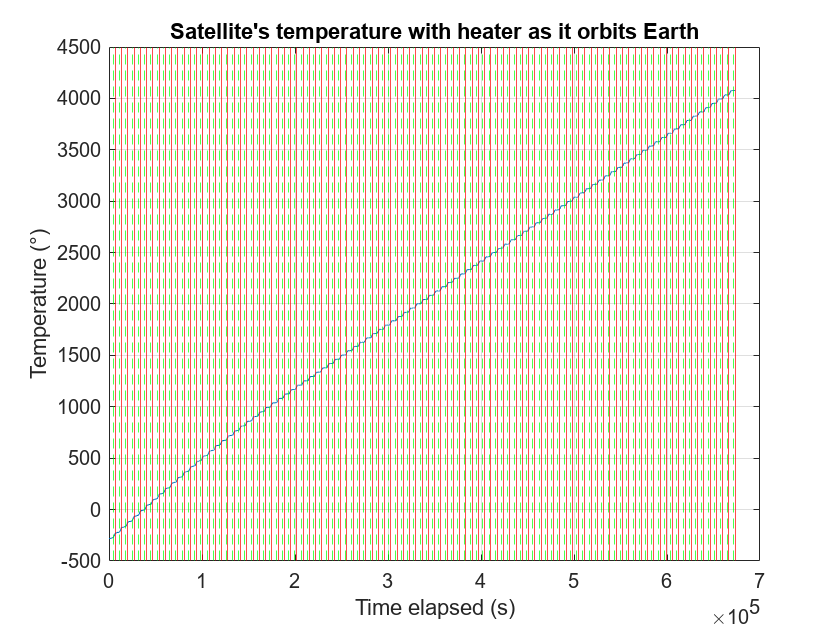

figure
plot(t_elasped, T_sat_Heater -273.15) %In degree as operational functionality also in degree
hold on
xlabel("Time elapsed (s)")
ylabel("Temperature (°)")
title("Satellite's temperature with heater as it orbits Earth")

% Add vertical lines for eclipse events
for i = 1:iterations
    xline(i * tau - t_eclipse, '--g')
    xline(i * tau, 'r')
end

grid on
hold off

Analyzing the graph, it is evident that the presented data yields illogical results when the temperature exceeds 4500 degrees. This anomaly likely stems from a calculation error by the author, which is unresolved. However, within the expected operational range of the graph (from -15 to 30 degrees), the variation aligns with the natural cold environment of space. A heater is required to maintain operational temperatures within these boundaries. I've selected 30W as a reference point, representing the minimum power necessary for a successful operational range. Anything beyond this would be economically impractical and unnecessary.

I've opted not to alter the materials or material absorption, as the code pertains to an already established satellite, not in its initial design stage. Implementing changes would prove challenging operationally, requiring disassembly and the establishment of new testing data to maintain the proper temperature range for the components. A heater offers a variable controller, which, in essence, is flexible, particularly crucial in the unpredictable and ever-changing space environment. Having a heater that can provide a specific amount of heat not only provides peace of mind but also grants mission control greater interaction during operations.

## Conclusion

his LiveScript has presented relevant equations to make informed predictions about the space environment and the thermal power input affecting the Earth-rotating spacecraft. These equations have been applied to the spacecraft "Sentinel B" to graph and plot the temperatures experienced, considering significant radiation influences in space. Through these calculations, I have offered pertinent recommendations for maintaining a specific temperature range during operation, elucidating the advantages of incorporating a heater into the assembly and operation processes.

# Communications Link Budget Analysis

### Introduction

This following section provides a calculation to the link margin for a specified antennae. Applying these calculation, an analysis will be conducted and a suggestion for the best antenna used would be provided visually. 

### Task 1: Identify the transmitting station

The transmitting station is the satellite and the ground station is the reciever. This is known as there is a downlink configuration present with the satellite's information, hence it is inputting data to the ground station. 

### Task 2: Variables

Defining mission-specfic vairables needed for the code. 

% Ground Station (GS) Properties
groundStationPower = 35;   % [W] Transmission Power of Ground Station
groundStationNoiseTemp = 257;  % [K] Noise Temperature of Ground Station
groundStationAntennaDiameter = 4.5;  % [m] Antenna Diameter of Ground Station

% Platform Communication Link Properties
bitErrorRate = 8 * 10^-6;   % Bit Error Rate
transmissionRate = 150;     % [Mbps] Transmission Rate
downlinkFrequency = 8.9;     % [GHz] Downlink Frequency 
implementationLosses = 1.85; % [dB] Implementation Losses 
additionalLosses = 7;        % [dB] Additional Losses

% Space Segment (SS) Properties 
transmissionPowerParabolic = 30;    % [W] Transmission Power for Parabolic Antennae  
transmissionPowerHelix = 90;        % [W] Transmission Power for Helix Antennae
transmissionPowerHorn = 54;         % [W] Transmission Power for Horn Antennae

noiseTempParabolic = 156;   % [K] Noise Temperature for Parabolic Antennae
noiseTempHelix = 160;       % [K] Noise Temperature for Helix Antennae
noiseTempHorn = 170;        % [K] Noise Temperature for Horn Antennae

antennaBeamwidthParabolic = 35;     % [°] Antenna Beamwidth for Parabolic Antennae
antennaBeamwidthHelix = 30;         % [°] Antenna Beamwidth for Helix Antennae
antennaBeamwidthHorn = 33;          % [°] Antenna Beamwidth for Horn Antennae

spaceSegmentMassParabolic = 30;     % [kg] Mass for Parabolic Antennae
spaceSegmentMassHelix = 12;         % [kg] Mass for Helix Antennae
spaceSegmentMassHorn = 2;           % [kg] Mass for Horn Antennae

boltzmannConstant = 1.38 * 10^(-23);  % [J/K] Boltzmann Constant 

% Array containing the three values of transmission power, one for each type of antenna
transmissionPowerArray = [transmissionPowerParabolic, transmissionPowerHelix, transmissionPowerHorn];


### Task 3: Calculate Antenna Gain

###  
$$antennaGain = \frac{EIRP}{Actual Transmitted Power}$$


#### Parabolic Antennas

From equation 8.21 of the course note:

### 
$$G=44\ldotp 3-10\log \left(\theta {\;}^2 \right)$$


- $G\;$= Parabolic gain 

- $\theta \;$= Antenna beam width 

parabolicGain = 44.3 - 10*log10(antennaBeamwidthParabolic^2);  %[dB] Parabolic gain 

#### Consdidering Helix Gain,

#### Helix Antennas

From equation 8.18 of the course note:

### 
$$G=10\ldotp 3+10\log \left({\left(\frac{52}{\theta \;}\right)}^2 \right)$$
    

- $G\;$= Helix gain 

- $\theta \;$= Antenna beam width 

helixGain = 10.3 + 10*log10((52/antennaBeamwidthHelix)^2);    %[db] Helix gain

#### Consdidering Horn Gain,

#### Horn Antennas

From equation 8.16 of the course note:

### 
$$G=20\log \left(\frac{255}{\theta \;}\right)-2\ldotp 8$$


- $G\;$= Horn gain        

- $\theta \;$= Antenna beam width 

hornGain = 20*log10(255/antennaBeamwidthHorn) - 2.8; %[db] Horn gain

#### Reformatting as an array

GainArray = [parabolicGain,helixGain,hornGain]; %Array of gain of different types of antennas

### Task 5: Effective Istrope Radated Power (EIRP)

Calculating EIRP 

From equation 8.10 of the course note:

### 
$$\textrm{EIRP}=G_T P_r$$


- $G_T \;$= Transmitter gain 

- $P_{T\;}$= Transmitter power 

Adding the gains of the Antenna to the log of the Transmission Power (Equation 8.10+8.5)

### 
$$\textrm{EIRP}=G_T \;+10\log_{10} \left(P_T \right)$$


EIRP_Array = GainArray + 10*log10(transmissionPowerArray);     %[W/m^2] Array of EIRP calulated for each Antenna 

### Task 6: Receive station's gain calculation

The following section provides the calculation needed to determine the gain at the recieve station. 

As the station uses parabolic, equation 8.20 of the textbook is valid. 

### 
$$G=17\ldotp 8+20\log \left(D\right)+20\log \left(f\right)$$


- $G$ = Gain

- $D$ = Dameter of the antenna 

- $f$ = Downlink frequency

GainGroundStation = 17.8 + 20*log10(groundStationAntennaDiameter) + 20*log10(downlinkFrequency);           %[dB] Gain at Receive Station

### Task 7: Calculate Gain-to-Noise Ratio

To calculate the Gain to noise ratio (GRN0R), it can be found between the ratio of gain at the recieve station and the noise temperature * Boltzmann constant. 

### $\textrm{GRN0R}=\frac{G_R }{{\textrm{kT}}_R }$r

- $\textrm{GRN0R}$ = Gain to noise ratio

- $G_R$ = Gain at the recieve station

- $T_R$ = Noise temperature

- $k$ = Boltzmann constant

Applying law of logs

### 
$$\left(\frac{G_R }{{\textrm{kT}}_R }\right)=10\log_{10} \left(G_R \right)-10\log_{10} \left(T_R \right)-10\log_{10} \left(k\right)$$


gainToNoiseRatio = GainGroundStation - 10*log10(groundStationNoiseTemp) - 10*log10(boltzmannConstant);     %[dB] Gain-to-Noise Ratio 

Gain is already presented as dB. 

### Task 8: Defining the Slant Range

 Found in the tutorial sheet and assume altitude goes from 250km to 2500km: 

### 
$$S=\sqrt{{\left(R_e +h\right)}^2 -{R_e }^2 }$$


- $S$ = Slant Range

- $R_e$= Radius of the earth 

- $h$ = atitude of the spacecraft

altitudeRange = linspace(250000,2500000,100); %[m] Linspace from 250km to 2500km
slantRange = sqrt(((R_E + altitudeRange).^2)-(R_E).^2);  %[m] Slant range 

### Task 9: Free space loss

Free space loss can be calculated using slant range calculated above:

From Equation 8.30 in the Course Notes:

### 
$$L_{\textrm{FS}} ={\left(\frac{4\pi \;S}{\lambda }\right)}^2$$


- $L_{\textrm{FS}} \;$= Free space loss [dB]

- $S$ = Slant range 

- 
$$\lambda =\frac{\textrm{SpeedOfLight}}{\textrm{DownLinkFrequency}}=\textrm{Wavelength}\;\left\lbrack m\right\rbrack$$


lambda  = (3*10^8)/(downlinkFrequency*10^9);  %[m] Wavelength
freeSpaceLoss   = 20*log10((4*pi*slantRange)./lambda);         %[dB] Free space loss

### Task 10: Carrier to Noise Density Ratio

Calculate the carrier to noise density ratio by applying the link budget equation.

Rearranging from equation 8.32 in the course notes:

### 
$$\frac{C}{N_O }=P_T G_T G_R \left(\frac{1}{L_{\textrm{FS}} }\right)\left(\frac{1}{L_{\textrm{add}} }\right)\left(\frac{1}{k}T_R \right)$$


Knowing that EIRP and GRN0R equals to the following:

### 
$$\textrm{EIRP}=P_T G_T ,\textrm{GRN0R}=\frac{G_R }{{\textrm{kT}}_R }$$
  

Carrier to nose density can be found as the following: 

### 
$$\frac{C}{N_0 }=\textrm{EIRP}+\textrm{GRN0R}-L_{\textrm{FS}} -L_{\textrm{add}}$$


The Link Budget Equation puts all the gains and losses (Losses due to energy dissapation, Atmospheric absorption, and additional losses)

carrierToNoiseRatio_P = EIRP_Array(1)+gainToNoiseRatio-freeSpaceLoss-additionalLosses;                              %[] CN0R for Parabolic Antenna 
carrierToNoiseRatio_He = EIRP_Array(2)+gainToNoiseRatio-freeSpaceLoss-additionalLosses;                            %[] CN0R for Helix Antenna
carrierToNoiseRatio_Ho = EIRP_Array(3)+gainToNoiseRatio-freeSpaceLoss-additionalLosses;                             %[] CN0R for Horn Antenna
carrierToNoiseRatio_Array= [carrierToNoiseRatio_P;carrierToNoiseRatio_He;carrierToNoiseRatio_Ho];                   %[] Array of CN0Rs

### Task 11: Find Energy per Bit Noise Density Ratio

Applying the carrier to noise ratio and transmission rate, energy per bit nose density ratio (EBN0) can be found. 

From Equation 8.23 from the Course Notes:

### 
$$t_b =\frac{1}{R_b }$$


- $t_b \;$= Time to recieve one bit

- $R_b$ = Data rate

From Equation 8.25 from the Course Nottes:

### 
$$\frac{C}{N_0 }=\frac{E_b }{N_0 }R_b$$


- $\frac{C}{N_0 }$ = Signal to noise ratio

- $E_b$ = Energy per bit 

- $R_b$= Data rate 

Hence:

### 
$$10\log_{10} \left(\frac{E_b }{N_0 }\right)=10\log_{10} \left(\frac{C}{N_0 }\right)-10\log_{10} \left(\frac{1}{t_b }\right)$$


timeOfBit = 1/(transmissionRate*10^6);                                                  %[s/Mb] Time to recieve one Bit
energyPerBitNoiseDensityRatio = carrierToNoiseRatio_Array - 10*log10(1/timeOfBit);      %[dB] Energy per Bit Noise Density Ratio

### Task 12: Probability of Error

Calculating the probability of error. (Between 0-15dB). 

energyPerBitRatio_estimation  = linspace(0,15,100);    %[dB] Array estimation 

Gven by the following equation in the tutorial sheet:

### 
$$P_e =\frac{1}{2}e^{-{10}^{\left(\frac{E_b }{N_{0\;\textrm{BER},\textrm{est}} }\times \frac{1}{10}\right)} }$$


Using an array of estimated values, the following code applies: 

ErrorProbability = 0.5*exp(-10.^(energyPerBitRatio_estimation.*(1/10)));   %[] Single orbit probarbilty of error 

### Task 13: EBN0 with the corresponding equired BER

Using the error probarbility and energy per bit ratio and given bit error rate, the appropriate EBN0 values are found from the following using interpt1 function. 

energyPerBitRatio_optimization =  interp1(ErrorProbability,energyPerBitRatio_estimation,bitErrorRate); %[] Using interpt1 function to find bit error rate matching bit EBN0 

### Task 14: Link Margins 

To determine the link margin for all atenna systemsm, the following formula applies: 

### 
$$\textrm{EBN0}-{\textrm{EBNO}}_{\textrm{optimized}\;} -\textrm{implementation}\;\textrm{losses}$$


Link_Margin = energyPerBitNoiseDensityRatio-energyPerBitRatio_optimization-implementationLosses;        %[dB] Link Margin

### Task 15: Display the resultant link margin values across the given altitude

The link margin can drawn against the altitude showing the change in downlink margins as the altitude of satellite increases.

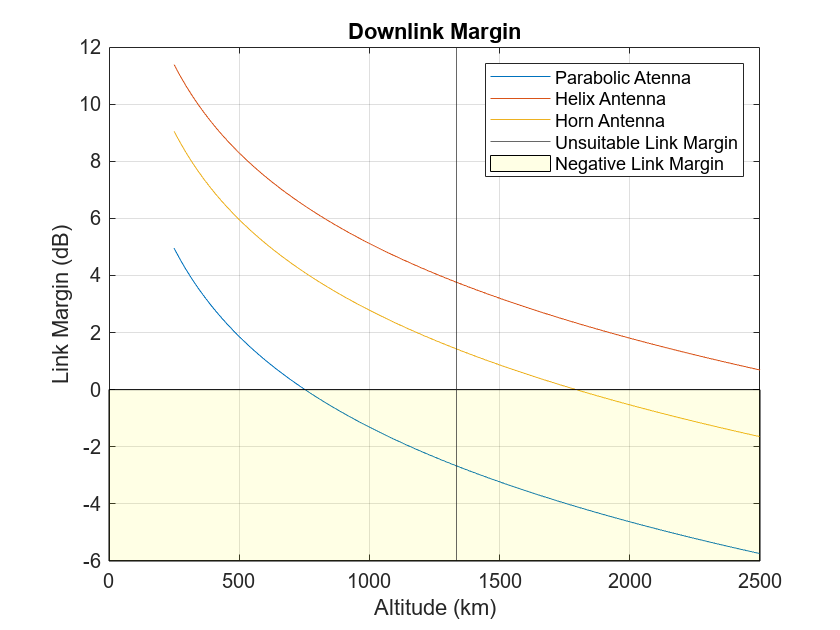

figure
hold on                        
grid on  
title("Downlink Margin")     
Range = altitudeRange / 1000;    
plot(Range,Link_Margin);   
xline(1336);
xlabel("Altitude (km)")         
ylabel("Link Margin (dB)")      
a = [0 -6; 0 0; 2500 0; 2500 -6;];
b = [1  2 3 4];
box on
patch('Faces',b,'Vertices',a,'FaceColor','yellow','FaceAlpha',.1);
legend("Parabolic Atenna","Helix Antenna","Horn Antenna","Unsuitable Link Margin","Negative Link Margin") 

## Discussion:

### 1) Based on your analysis are all avaible systems sutiable for use in the Sentinel-6B mission at the chosen orbital altitude?

- Parabolic antennas are deemed unsuitable for the spacecraft, as indicated by a negative link margin at the mission altitude.

- Helix antennas demonstrate a positive link margin at the given altitude, thus affirming their capability for the mission.

- Horn antennas are also deemed suitable at the specified altitude, exhibiting the ability to achieve the mission goal at an altitude of 1336 km.

This assessment provides a clear overview of the compatibility of different antenna systems with the Sentinel-6B mission requirements at the chosen orbital altitude.

#### 2)  What Antenna System would you recommend and why?

In light of the exclusion of parabolic antennas due to their unsuitability for the Sentinel-6B mission, the author recommends the adoption of helix antennas. This choice is substantiated by several factors contributing to the overall superior performance of helix antennas compared to horn antennas.

Helix antennas exhibit higher efficiency owing to their specific design shape and structure, resulting in increased gain. In contrast, horn antennas may offer comparable performance but at a potentially higher cost and weight, coupled with a narrower frequency range (300MHz - 3GHz).

The graph analysis further supports the preference for helix antennas, indicating a more substantial area within the positive link margin region. This characteristic grants helix antennas greater flexibility to operate effectively at various altitudes. In contrast, horn antennas experience a negative link margin around 1800km, limiting their adaptability.

Considering these factors, the author recommends the utilization of helix antennas for the Sentinel-6B mission. Their enhanced performance, efficiency, and flexibility make them the more suitable choice compared to horn antennas, aligning with the mission requirements.

### 3) Changing Single Link Parameters

The author suggests the following modifications to improve a single link parameter by a factor of 2, benefiting the mission and its results:

Ground Segment:

- Increase Antenna Diameter: This is considered the more straightforward option in terms of assembly and maintenance. It can significantly enhance the link margin and even revive the parabolic antenna as a viable option for the mission. The larger antenna diameter provides more allowance, contributing to improved link performance.

- Decrease Noise Temperature: While this has a small influence on the link margin, the impact may not be significant enough to warrant a change. Therefore, the author suggests focusing on increasing the antenna diameter as the primary modification.

- Increase Transmission Power: The author notes that increasing transmission power does not influence the link margin as it is receiving. Therefore, this parameter is not recommended for modification in the ground segment.

Space Segment:

- Decrease Antenna Beamwidth: Although decreasing antenna beamwidth increases the link margin for all antennas, the author acknowledges that it is economically unfriendly and complex to implement. This option might be considered based on mission resources and funding availability.

- Decrease Noise Temperature: Similar to the ground segment, decreasing noise temperature has a small influence on the link margin, but it may not be significantly impactful.

- Increase Transmission Power: The author notes that increasing transmission power by 2 can increase the link margin for all antennas in the space segment. However, it is considered non-conventional and may have assembly challenges.

In conclusion, the author recommends focusing on increasing the antenna diameter at the ground segment as a practical and effective modification. If further improvements are needed, the option of decreasing antenna beamwidth in the space segment could be considered, weighing the economic and complexity factors. The decision may depend on the mission's available resources and funding constraints.

### **Conclusion**

This LiveScript has covered the completion of tutorial 3 as part of the AERO21111 Space Systems MATLAB coursework. This LiveScript shown relevant equations to establish an educated prediction of the communication and influence acting on both ground and space segments of the mission. I have used this equations and applied in into the Spacecraft "Sentinel B" to grapse and plot the link margin vs different types of antennas  the spacecraft expierence with consideration of realstic losses in operation. Using these calculations I have provided relevant reccomedation on maintaining a specifc temperature range within operation, and oosing the suitable antenna type and mission parameter.

# Attitude Determination and Control System

### Introduction

The LiveScript for the AERO21111 Space Systems module, covering the response to MATLAB tutorial 4, is designed to analyze the attitude of the satellite and determine its torque variation throughout its orbit. Additionally, it aims to propose a suitable control system for managing the spacecraft's attitude while assessing the impact of integrating this control system.

Throughout this document, I will conduct an in-depth analysis of the satellite's attitude and its torque changes during the orbit. Subsequently, I will present a recommendation for a control system tailored to the satellite's requirements. The implementation and effect of this control system on the spacecraft's attitude will be thoroughly examined, providing valuable insights into the overall performance of the satellite.

### Task 1:  Defining variables 

As always, we define variables given for our mission. 

% Step 1 - Define the various inputs and physical constants
radiusEarth = 6371e3;                    % Radius of Earth, m
gravitationalParameterEarth = 3.986e14;  % Standard gravitational parameter of Earth, m^3*s^-2
altitudes = [1000e3, 1336e3, 2000e3];    % Array of altitudes, m
massMomentInertiaZZ = 40;                % Mass moment of inertia about the z-axis, kg/m^2
massMomentInertiaYY = 25;                % Mass moment of inertia about the y-axis, kg/m^2
crossSectionalAreaSatellite = 3.35;      % Cross sectional area of the satellite, m^2
distanceCenterMassAeroPressure = 0.4576; % Distance from centre of mass to centre of aerodynamic pressure, m
densityADCS = [3e-15, 8.5e-16, 7e-17];   % Array of density, kg*m^-3
dragCoefficient = 2.2;                   % Coefficient of drag

### Task 2 - Calulating Torque due to Gravity

To calculate torque from different gardients of gravity, new functions is used for the calculation of velocity, gravity torque, and amosphereic drag torque. The following equations are found within 3.8, 3.9 of the course note, and tutorial sheet:

velocity = zeros(1, length(altitudes));
gravityTorque = zeros(1, length(altitudes));
dragTorque = zeros(1, length(altitudes));

for n = 1:length(altitudes)
    velocity(n) = calculateOrbitalVelocity(radiusEarth + altitudes(n), gravitationalParameterEarth);
    gravityTorque(n) = getGravityTorqueMax(massMomentInertiaZZ, massMomentInertiaYY, radiusEarth + altitudes(n), gravitationalParameterEarth);
    dragTorque(n) = getDragTorque(densityADCS(n), dragCoefficient, crossSectionalAreaSatellite, velocity(n), distanceCenterMassAeroPressure);
end


### Task 3 - Finding the orbit period 

#### Orbital period

#### 
$$\tau =2\pi \;\sqrt{\frac{r^3 }{\mu }}$$
 

- $\tau$  = Orbital period

- $r$ = Orbital radius, assuming a circular orbit where eccentricity = 0

- $\mu$ = Gravitiational Parameter

orbitPeriods = 2 * pi * ((radiusEarth+altitudes).^3 / gravitationalParameterEarth).^(1/2);

### Task 4 - Finding the total torque over time

Using function handle in MATLAB to determine the total torque over time. [Equation 2 from tutorial sheet]

#### 
$$f\left(t\right)=\cos \left(\frac{t}{\tau }2\pi \;\right)T_G +T_D$$


- $t$  = Time

- $\tau$  = Orbital period

- $T_G$ = Torque due to gravity

- $T_D$ = Torque due to amosphereic drag

torqueTotal1 = @(t) cos(t./orbitPeriods(1)*2*pi) .* gravityTorque(1) + dragTorque(1);
torqueTotal2 = @(t) cos(t./orbitPeriods(2)*2*pi) .* gravityTorque(2) + dragTorque(2);
torqueTotal3 = @(t) cos(t./orbitPeriods(3)*2*pi) .* gravityTorque(3) + dragTorque(3);

### Task 5 -Total momentum storage over one orbit 

Using the intergral function to determine the total angular momentum storage over one orbit.

% Task 5 - Calculate the momentum storage that is required over one orbit (H)
momentumStorage = zeros(1, length(altitudes));
for n = 1:length(altitudes)
    momentumStorage(n) = integral(@(t) cos(t./orbitPeriods(n)*2*pi) .* gravityTorque(n) + dragTorque(n), 0, orbitPeriods(n));
end


### Task 6 - Plotting

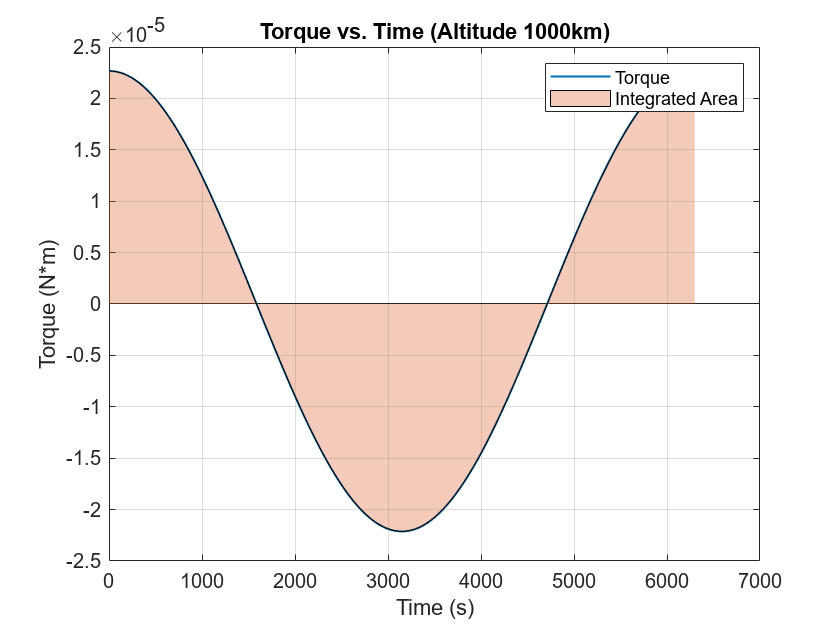

% Task 6 - Plot a graph of torque vs time
figure(1)
time1 = linspace(0, orbitPeriods(1), 1000);
plot(time1, torqueTotal1(time1), 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Torque (N*m)');
title('Torque vs. Time (Altitude 1000km)');
grid on;
hold on;
area(time1, torqueTotal1(time1), 'FaceAlpha', 0.3);
legend('Torque', 'Integrated Area');
hold off;

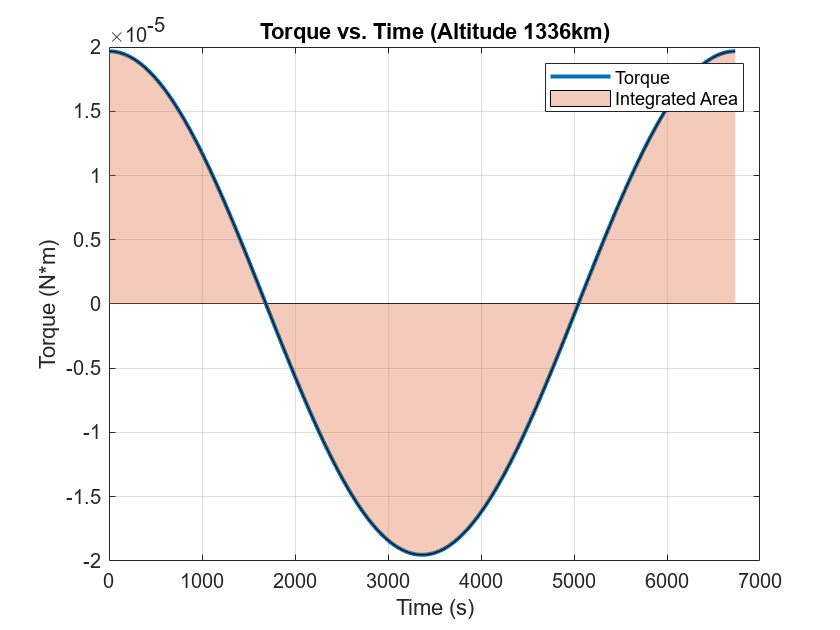

figure(2)
time2 = linspace(0, orbitPeriods(2), 1000);
plot(time2, torqueTotal2(time2), 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Torque (N*m)');
title('Torque vs. Time (Altitude 1336km)');
grid on;
hold on;
area(time2, torqueTotal2(time2), 'FaceAlpha', 0.3);
legend('Torque', 'Integrated Area');
hold off;

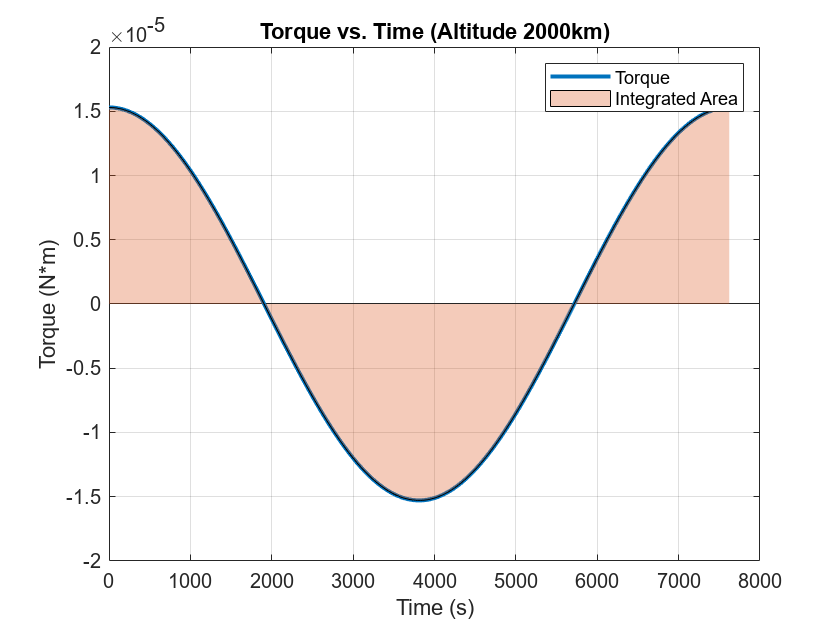

figure(3)
time3 = linspace(0, orbitPeriods(3), 1000);
plot(time3, torqueTotal3(time3), 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Torque (N*m)');
title('Torque vs. Time (Altitude 2000km)');
grid on;
hold on;
area(time3, torqueTotal3(time3), 'FaceAlpha', 0.3);
legend('Torque', 'Integrated Area');
hold off;

## **Discussion**

### 1) What changes could be made to the satellite to stop the torque from varying across the orbit?

There are various components on board a spacecraft capable of mitigating torque variations throughout its orbit. The spin-stabilized spacecraft offers a straightforward and cost-effective means of maintaining torque stability. It relies on momentum bias to achieve gyroscopic rigidity, effectively countering torque generated during the orbit period. However, a limitation is that the spin axis must remain constant throughout the mission, restricting the spacecraft's ability to adjust axial deflection, which may be critical when the spacecraft is offset in orbit. Additionally, the spin-stabilized configuration can affect the direction in which antennas are pointing, a significant constraint for communication-focused satellites as it may pose challenges in maintaining reliable communication links.

On the other hand, the 3-axis stabilized spacecraft provides greater maneuverability than the spin-stabilized counterpart through the use of momentum and reaction wheels. However, this method is economically expensive to assemble and operate. The distribution of mass also plays a crucial role in torque management. A symmetric and 0-torque clean configuration would help reduce the generation of unwanted torques and assist the spacecraft in returning to its natural position.

The active control system combines the 3-axis stabilized spacecraft with electronic components and thrust generation for even more precise control. However, implementing features such as an ion thruster or electronic components could increase electronic consumption and elevate the risk of sectional electrical failures onboard.

Passive torque reduction through fluid dynamics onboard is also possible. However, since this approach reacts to external forces passively, it cannot be easily controlled. Software algorithms could potentially offer elementary solutions, but human control remains challenging.

### **2) **In this model we have neglected the disturbance torques due to magnetic effects and solar radiation. Is this a reasonable assumption?

As a low Earth orbiting satellite, the author deems it reasonable to assume that magnetic influence is relatively lower at lower altitudes. Regarding solar radiation, the torque generated due to varying thermal heat input could create an imbalance of forces. However, the author believes that with the implementation of an effective thermal damping system or thermal-resistant materials, neglecting solar radiation becomes reasonable.

Despite the magnitude of these influences remaining relatively small, their combination could eventually lead to a visual change in the orbit's trajectory. It is crucial to ensure the existence of a system to counteract these subtle forces, such as a passive damping system or a coating of thermal-resistant material.

### 3) Suggest a suitable attitude control system for the spacecraft based on your results?

I have chosen the NanoAvionics - 4RW0 as the attitude control system for this spacecraft. The 4RW0 offers a 3-axis precise control utilizing its four flywheels. It boasts a relatively low mass compared to other components and maintains operational temperatures corresponding to our mission specifications outlined in tutorial 2. Notably, it features low power consumption, which can be efficiently supplied by a solar panel on the spacecraft given its modest requirements.

It is important to note, however, that the torque generated by the NanoAvionics - 4RW0 is relatively lower compared to some alternative components. This lower torque may result in a slower transition stage or correcting phase of the spacecraft. Nonetheless, the overall advantages, including precise control, low mass, and compatibility with our mission's operational temperatures, make the NanoAvionics - 4RW0 a suitable choice for the attitude control system.

Mass = 0.137kg 

Power Consumption = 0.15 to 0.6W. 

### **Conclusion**

This LiveScript has covered the completion of tutorial 4 as part of the AERO21111 Space Systems MATLAB coursework. This LiveScript shown relevant equations to establish an educated prediction of the torque and other influence acting on both spacecraft itself. I have identitfy the correct equations and applied in into the Spacecraft "Sentinel B" to grapse and plot the torque it expierence throughout orbit. Using these calculations I have provided relevant reccomedation on a new altitude control system, which could be used to offset different influence within the space enviornment.  

# Power and Mass Budget Analysis 

### Introduction

This LiveScript covers the response to MATLAB tutorial 5 as required for the AERO21111 Space Systems module. The following sesction provides the calculation and analysis of the overall power consumption do an analysis of the overall power consumption and the mass budget of the satellite.

### Task 1:  Mission Lifetime

An estimation of mission life time is needed to calculate the recharge cycle and the orbital Period. The misison life is found by the following:


$$\textrm{Mission}\;\textrm{Life}\;\textrm{in}\;\textrm{yrs}=\;\frac{\textrm{Recharge}\;\textrm{Cycles}\times \;\tau }{60\times 60\times 24\times 365}$$


- $\tau$ is the orbital period

recharge_cycle = 25000;             % [-]Estimated number of recharge cycles 
discharge_depth = 0.5;       % [-] Depth of Discharge
energy_density = 120;        % [W*hrs*kg^(-1)] Energy density

Time1 = floor(recharge_cycle * (tau * 3.1689 * 10^(-8)))

Time1 = 5

To provide an accurate estimation and provde a careful calculation of the estimated errs, and satellites' lifespan, the floor's function is to be used to ensure that the estimate provided in the following code are benefitical within the operational and assembly process of the mission. 

### Task 2: Overall power demands [Eclipse]

Define the power variables of the satellite

% Power Requirements
SV_bus = 18;                             %[V] Output volatage of Satellite Bus
P_payload = 350;                         %[W] Power of Payload
P_thermal = 150;                         %[W] Power of thermal subsystem
P_heater = 30;                           %[W] Power of Heater (as definied in tutorial 2)
P_communication = 240;                   %[W] Power of communications subsystem
P_transmission = transmissionPowerHelix; %[W] Power of Transmission Power
P_ADCS = 110;                            %[W] Power of ADCS Ssbsystem
P_reaction_wheel = 0.6;                  %[W] Power of self chosen reaction wheel 
P_other = 150;                           %[W] Power of sub-systems

The reaction wheel power requirement used is the biggest of the range. 

$P_{Total}$ = $\sum$Power Requirements

$P_{eclipse}$ = $\sum$Thermal + 0.5*Communication + Transmission + 0.5* ADCS + Reaction Wheel + 0.5*P_other

P_total = P_payload + P_thermal + P_heater + P_communication + P_transmission + P_ADCS + P_reaction_wheel + P_other

P_total = 1.1206e+03

P_eclipse = round(P_thermal + (P_communication/2) + P_transmission + (P_ADCS/2) + P_reaction_wheel + (P_other/2))

P_eclipse = 491

### Task 3: Total Battery Capacity 

To calculate Total Battery Capacity:


$$C_B =\frac{P_{\textrm{eclipse}} \;t_e }{\textrm{DOD}\;V_B }$$


- $C_B$ = Total Battery Capacity

- $P_{\mathrm{eclipse}\;}$= Power Required during the eclipse period

- $t_e$ = Duration of Eclipse Period in hrs

- $\mathrm{DOD}$ = Depth of Discharge

- $V_B$ = Voltage Bus

C_B = (P_eclipse * (t_eclipse * 0.000277778) / (discharge_depth * SV_bus));  %Ampere-Hours

### Task 4: Total Energy of Storage System

Total energy of storage system is calculated using:


$$\in \;=C_B \;V_B$$
 

- $\in$ is the energy stored in Wh

- $C_B$ is the Total Battery Capacity

- $V_B$ is the Voltage Bus

total_energy = C_B * SV_bus;

### Task 5: Mass of the battery

The mass of the battery can be found by the following: 


$$M_{\textrm{battery}} =\frac{\in }{\bar{\in} }$$
 

- $M_{\textrm{battery}}$ is the mass of Battery

- $\in$ is the Energy Stored

- $\bar{\in}$ is the Energy Density in Wh/kg

Battery_mass = round(total_energy / energy_density)

Battery_mass = 5

### Task 6 - Idenify and Define Constants

Below all the constants given in table 3 are defined:

efficiency_cell = 0.2;                % 20% cell efficiency 
degradation_per_year = 0.05;          % Degradation per year (Starting at 5%)
packingfficiency = 0.9;             % 90% Packing efficiency is 
average_sun_angle = 40;               % Angle to the sun
array_output_voltage = 24;            % Array output voltage 

### Task 7 -  Calculate charging rate

While the spacecraft is in the sunlight the spacecraft is charging. Recharge rate can be found using the equation:


$$R_{\textrm{ch}} =\frac{\textrm{DOD}\;C_B }{t_s }$$


- $R_{\textrm{ch}}$ = Battery charge rate

- $\textrm{DOD}$ = Depth of discharge

- $C_B$ = Total Battery Capacity

- $t_s$ is time spent in sunlight during orbit

Time spent in sunlight was calculated in Tutorial 1 and defined as t_sun.

sun_recharge = (discharge_depth * C_B) / (t_sun * 0.000277778);

### Task 8 - Calculate Total Power Of Array

To calculate the total power demands that is required of the solar array, the sum of all power used during the stallite is used. 


$$P_{\textrm{EOL}} =P_{\left(\textrm{payload}+\textrm{services}\right)} +R_{\textrm{ch}} V_A$$


- $P_{\textrm{EOL}}$ = End of life power required

- $P_{\left(\textrm{payload}+\textrm{services}\right)}$ = Power of payload and services

- $R_{\textrm{ch}}$ = Recharge rate of battery

- $V_A$ = Array output voltage

P_sun = P_payload + 150 + P_communication + P_transmission + P_ADCS + P_reaction_wheel + P_other;
total_power = ceil(P_sun + (sun_recharge * array_output_voltage));

### Task 9 - Area of the Solar Array

The area of the solar array can be found using the following equation:


$$P=q_s A\eta_p \eta$$


- $q_s$ = Solar insolation

- $A$ = Area of the Solar Array

- $\eta_p$ = Packing efficiency

- $\eta$ = Cell efficiency

solar_panel_area = ceil(total_power / (q_s * efficiency_cell * packingfficiency * (1 - degradation_per_year) * cosd(average_sun_angle)));

### Task 10 - Mass of the Solar Panels

Finding the mass of solar panels using area of solar array:

mass_array = (150/15)*solar_panel_area;  %[kg] Mass of Solar Array
mass_area = 150 / 15;  
solar_mass = ceil(solar_panel_area * mass_area)

solar_mass = 80

## Discussion


$$\left[\matrix
{\textbf{Sub-System Element}
& \textbf{Sentinel 6-A [W]} & \quad
& \textbf{Sentinel 6-B [W]} & \quad \cr
\textrm{Payload} & 350 & \quad & 350 \cr
\textrm{Thermal Subsystem} & 150 & \quad & 150 \cr
\textrm{Heater} & N/A & \quad &  30 \cr
\textrm{Communications Subsystem} & 240 & \quad & 240 \cr
\textrm{Transmission Power} & 30 & \quad & 90 \cr
\textrm{ADCS Subsystem} & 110 & \quad & 110 \cr
\textrm{Reaction Wheels} & N/A & \quad & 0.6 \cr
\textrm{All Other Subsystems} & 150 & \quad & 150 \cr
\textrm{\textbf{Total}} & 1030 & \quad & 1120.6 \cr
}\right]$$



$$\left[\matrix
{\textbf{Sub-System Element}
& \textbf{Sentinel 6-A [/kg]} & \quad
& \textbf{Sentinel 6-B [/kg]} & \quad \cr
\textrm{Payload and Structure} &465 & \quad & 465 \cr
\textrm{Thrusters} & 50 & \quad & 50 \cr
\textrm{Manouvering Fuel} & 130 & \quad & 130 \cr
\textrm{De-Orbit Fuel} & N/A & \quad & 779.201\cr
\textrm{Thermal Subsystem} & 40 & \quad & 40 \cr
\textrm{Heater} & N/A & \quad & 5 \cr
\textrm{Communications Subsystem} & 70 & \quad & 70 \cr
\textrm{Transmission Antenna} & 30 & \quad & 12 \cr
\textrm{ADCS Subsystem} & 60 & \quad & 60 \cr
\textrm{Reaction Wheels} & N/A & \quad &0.665 \cr
\textrm{Power Distribution System} & 50 & \quad & 50 \cr
\textrm{Power Regulation and Control System} & 70 & \quad & 70 \cr
\textrm{Energy Storage System} & 15 & \quad & 5 \cr
\textrm{Solar Array} & 150 & \quad & 80 \cr
\textrm{\textbf{Total}} & 1130 & \quad & 1816.875 \cr
}\right]
$$


**Within this report throughout the 5 sections, I have caluculated the total power and total mass needed for Sentinel 6B's mission. Despite an incomplete calculation on tutorial 2, the total mass concludes at ~1820kg and total power consumption concludes at around 1121W. The majority of the change was introduced with the introduction of an deorbit fuel with respect to the delta V needed to maintain orbit. A helix satellite antenna for communication, a heater to maintain operational range and provide functionality for temperature senitvity components, and a reaction wheel to control externaltorques and precious control over the 3 axis. - Summarising the surplus of around 700kg from Sentinel 6As' mission. **

#### Conclusion

This LiveScript has covered the completion of tutorial 5 as pequations needed to calculate the total power required and the total mass of the solar array. I have summarised together the mass and power introduced in former tutorials and determined the total surpluse in power requirements and total mass. I have also justified my choices for all parts of the coursework. 

#### Orbital Velocity

### 
$$v=\sqrt{\frac{\mu \;}{r}\;}$$


- $v$ = Orbital velocity

- $\mu$ = Graviational parameter

- $r$ = Radius of orbit

function velocity = calculateOrbitalVelocity(radius, gravitationalParameter)
    velocity = sqrt(gravitationalParameter / radius);
end

#### Torque due to gravity 

 Using Equation 9.6 from the Course Notes;

### 
$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\;\sin \left(2\vartheta \right)$$


- $\mu$ = Gravitiational parameter

- $R$ = radius of orbit 

- $I_{\textrm{ZZ}}$ = Mass Moment of Inertia along the Y-Axis

- $I_{\textrm{YY}}$ = Mass Moment of Inertia along the X-Axis 

- $\vartheta$ = $\theta$ betweeen the spacecraft body Z axis and the local vertical. (Assumed to be 45) 

function gravityTorqueMax = getGravityTorqueMax(momentInertiaZZ, momentInertiaYY, radius, gravitationalParameter)
    rollAngle = 45; % assume roll angle of aircraft is 45 degrees
    gravityTorqueMax = (3 * gravitationalParameter) / (2 * radius^3) * abs(momentInertiaZZ - momentInertiaYY) * sind(2 * rollAngle);
end

#### Torque due to drag 

Using Equation 1 from the Tutorial Sheet:

### 
$$T_D =\frac{1}{2}\rho C_d {\textrm{AV}}^2 \left(C_{\textrm{pa}} -C_g \right)$$


- $T_D$ = Torque due to Drag 

- $\rho \;$= Density 

- $C_d$ = Coeffiecent of drag

- $A$ = Cross-sectional area of the spacecraft

- $V$= Orbit velocity

- $\left(C_{\textrm{pa}} -C_g \right)$ = Distance from the center of mass to the center of gravity

function dragTorque = getDragTorque(density, dragCoefficient, area, velocity, distance)
    dragTorque = 0.5 * density * dragCoefficient * area * velocity^2 * distance;
end